clc
clear
close all
set(0,'defaultAxesFontSize', 12)
set(0, 'DefaultLineLineWidth', 2);

rng(1)
% You will implement regularized logistic regression to predict whether
% microchips from a fabrication plant passes quality assurance (QA).
% During QA, each microchip goes through various tests to ensure it is
% functioning correctly. Suppose you are the product manager of the
% factory and you have the test results for some microchips on two different
% tests. From these two tests, you would like to determine whether the
% microchips should be accepted or rejected. To help you make the decision,
% you have a dataset of test results on past microchips,
% from which you can build a logistic regression model.

## Load Data

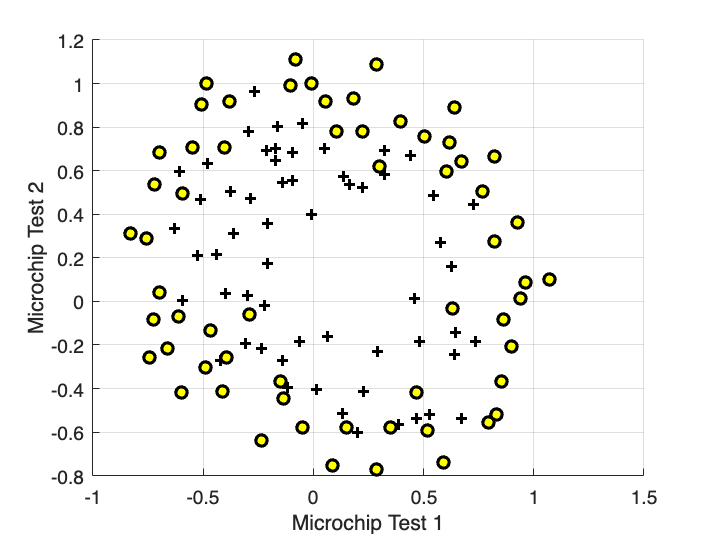

data = load('Data/ex2data2.txt');
X = data(:, [1, 2]); % regressors (features) matrix
y = data(:, 3); % labels


plotData(X, y);
grid on;
xlabel('Microchip Test 1')
ylabel('Microchip Test 2')



% The above figure shows that our dataset cannot be separated into positive
% and negative examples by a straight-line through the plot.
% Therefore, a straight-forward application of logistic regression
% will not perform well on this dataset since logistic regression will only
% be able to find a linear decision boundary.

## Polynomial features

% Add Polynomial Features

% Note that mapFeature also adds a column of ones for us, so the intercept
% term is handled
degree = 6; % degree of polynomial features
X_map = mapFeature(X(:,1), X(:,2), degree); % create polynomial features

% Get train and test data
cv = cvpartition( size(X,1), 'HoldOut', 0.3); % partition data 70% train - 30% validation
idx = cv.test; % get index of validation data

X_train = X_map(~idx, :); % train data
X_validation = X_map(idx, :); % validation data
y_train = y(~idx, :); % train labels
y_validation = y(idx, :); % validation labels

## ============= Regularizied logistic regression =============

% Initialize fitting parameters
initial_theta = zeros(size(X_train, 2), 1);

% Set regularization parameter lambda to 0 (you should vary this)
lambda = 0;

% Compute and display initial cost and gradient for regularized logistic
% regression
[cost, grad] = costFunctionReg(initial_theta, X_train, y_train, lambda);

J = 57.5312


fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 57.531216




% Set Optimization Options
options = optimset('GradObj', 'on', 'MaxIter', 400);

% Optimize
[theta, J, exit_flag] = ...
    fminunc(@(t)(costFunctionReg(t, X_train, y_train, lambda)), initial_theta, options);

J = 57.5312

J = 50.1695

J = 45.0262

J = 40.4994

J = 33.6092

J = 31.3780

J = 27.8860

J = 26.4659

J = 25.6842

J = 25.1982

J = 24.7271

J = 24.2372

J = 23.8122

J = 23.5371

J = 23.4114

J = 23.3581

J = 23.3309

J = 23.3054

J = 23.2630

J = 23.2111

J = 23.1224

J = 22.9752

J = 22.7775

J = 22.6325

J = 22.5847

J = 22.5696

J = 22.5613

J = 22.5532

J = 22.5372

J = 22.5096

J = 22.4586

J = 22.3756

J = 22.2715

J = 22.1970

J = 22.1712

J = 22.1639

J = 22.1578

J = 22.1448

J = 22.1154

J = 22.0502

J = 21.9397

J = 21.8035

J = 21.7222

J = 21.7094

J = 21.6993

J = 21.6815

J = 21.6536

J = 21.6247

J = 21.6086

J = 21.6039

J = 21.6026

J = 21.6003

J = 21.5946

J = 21.5809

J = 21.5487

J = 21.4819

J = 21.3723

J = 21.2515

J = 21.1972

J = 21.1899

J = 21.1882

J = 21.1878

J = 21.1864

J = 21.1845

J = 21.1791

J = 21.1666

J = 21.1350

J = 21.0635

J = 20.9290

J = 20.7810

J = 20.7183

J = 20.7083

J = 20.7066

J = 20.7058

J = 20.7046

J = 20.7022

J = 20.6965

J = 20.6830

J = 20.6518

J = 20.5906

J = 20.5051

J = 20.4398

J = 20.4234

J = 20.4222

J = 20.4217

J = 20.4206

J = 20.4186

J = 20.4131

J = 20.3997

J = 20.3661

J = 20.2891

J = 20.1439

J = 19.9676

J = 19.8664

J = 19.8487

J = 19.8474

J = 19.8468

J = 19.8463

J = 19.8461

J = 19.8461

J = 19.8460

J = 19.8457

J = 19.8451

J = 19.8436

J = 19.8398

J = 19.8300

J = 19.8052

J = 19.7440

J = 19.6049

J = 19.3483

J = 19.0359

J = 18.7908

J = 18.6436

J = 18.5902

J = 18.5765

J = 18.5695

J = 18.5666

J = 18.5656

J = 18.5652

J = 18.5651

J = 18.5650

J = 18.5647

J = 18.5643

J = 18.5633

J = 18.5611

J = 18.5558

J = 18.5428

J = 18.5114

J = 18.4367

J = 18.2758

J = 18.0347

J = 17.8755

J = 17.8269

J = 17.8163

J = 17.8136

J = 17.8125

J = 17.8120

J = 17.8118

J = 17.8116

J = 17.8114

J = 17.8111

J = 17.8103

J = 17.8085

J = 17.8041

J = 17.7929

J = 17.7651

J = 17.6988

J = 17.5572

J = 17.3211

J = 17.0408

J = 16.7716

J = 16.5103

J = 16.3936

J = 16.3744

J = 16.3658

J = 16.3629

J = 16.3604

J = 16.3584

J = 16.3566

J = 16.3558

J = 16.3553

J = 16.3549

J = 16.3542

J = 16.3531

J = 16.3509

J = 16.3473

J = 16.3416

J = 16.3325

J = 16.3164

J = 16.2835

J = 16.2119

J = 16.0582

J = 15.7510

J = 15.2009

J = NaN

J = 14.7353

J = NaN

J = NaN

J = 14.6835

J = NaN

J = NaN

J = 14.6691

J = 14.5441

J = NaN

J = NaN

J = 14.5104

J = NaN

J = NaN

J = NaN

J = 14.5102

J = 14.5090

J = 14.4981

J = NaN

J = NaN

J = 14.4950

J = 14.4677

J = NaN

J = NaN

J = NaN

J = 14.4676

J = 14.4675

J = 14.4663

J = NaN

J = NaN

J = 14.4659

J = NaN

J = 14.4644

J = NaN

J = NaN

J = NaN

J = 14.4644

J = 14.4644

J = 14.4643

J = NaN

J = NaN

J = 14.4643

J = NaN

J = 14.4642

J = NaN

J = NaN

J = 14.4642

J = NaN

J = NaN

J = NaN

J = 14.4642

J = 14.4642

J = 14.4642

J = NaN

J = NaN

J = 14.4642

J = NaN

J = 14.4642

J = NaN

J = NaN

J = NaN

J = 14.4642

J = 14.4642

J = 14.4642

J = NaN

J = NaN

J = 14.4642

J = NaN

J = NaN

J = 14.4642

J = NaN

J = NaN

J = 14.4642

J = 14.4642

J = NaN

J = NaN

J = 14.4642

J = NaN

J = NaN

J = 14.4642

J = NaN

J = NaN

J = 14.4642

J = NaN

J = NaN

J = 14.4642

J = 14.4642

J = NaN

J = NaN

J = NaN

J = 14.4642

J = 14.4642

J = 14.4642

J = NaN

J = NaN

J = 14.4642

J = 14.4642

J = NaN

J = NaN

J = NaN

J = 14.4642

J = 14.4642

J = 14.4642

J = NaN

J = 14.4642

J = NaN

J = NaN

J = NaN

J = 14.4642


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>


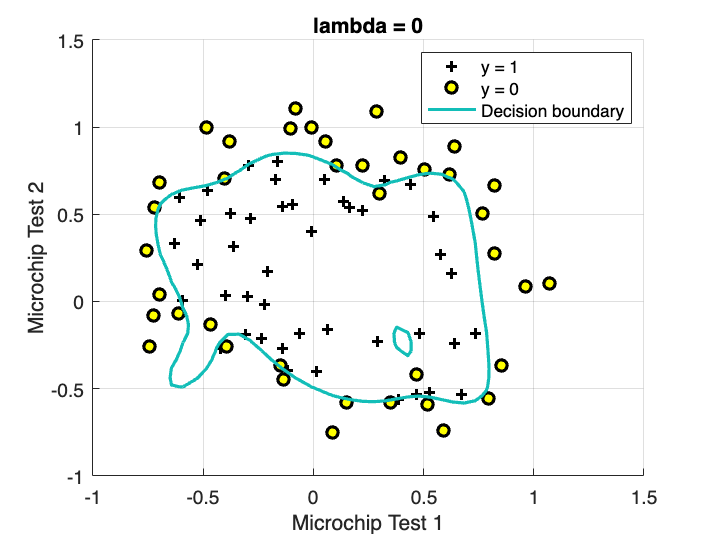


% Plot Boundary
plotDecisionBoundary(theta, X_train, y_train, degree);
hold on;
title(sprintf('lambda = %g', lambda))
xlabel('Microchip Test 1');
ylabel('Microchip Test 2');
grid on;
legend('y = 1', 'y = 0', 'Decision boundary')


% Get classification estimates
p_train = predict(theta, X_train); % classification on train data
p_validation = predict(theta, X_validation); % classification on validation data

% Compute classification accuracy
fprintf('Train Accuracy: %f\n', mean(double(p_train == y_train)) * 100);

Train Accuracy: 8.433735


fprintf('Validation Accuracy: %f\n', mean(double(p_validation == y_validation)) * 100);

Validation Accuracy: 28.571429


## A simple validation procedure

degree_max = 10; % max polynomial degree for polynomial features
accuracy_train = zeros(degree_max, 1);
accuracy_validation = zeros(degree_max, 1);

for degree = 1 : 1 : degree_max  % degree of polynomial features
    
    X_map = mapFeature(X(:,1), X(:,2), degree); % map original features to polynomial features
    
    X_train = X_map(~idx, :); % train data
    X_validation = X_map(idx, :); % validation data
    
    
    % fit not regularized logistic regression model
    mdl = fitglm(X_train, y_train, 'Distribution', 'binomial');
    
    % Obtain probability estimates
    yhat_train_probs = predict(mdl, X_train); % estimates
    yhat_test_probs = predict(mdl, X_validation);
    
    % Threshold the estimated probabilities to obtain a classification result
    yhat_train_class = yhat_train_probs > 0.5;
    yhat_test_class = yhat_test_probs > 0.5;
    
    % Compute accuracy
    accuracy_train(degree) = mean(yhat_train_class == y_train);
    accuracy_validation(degree) = mean(yhat_test_class == y_validation);
    
end

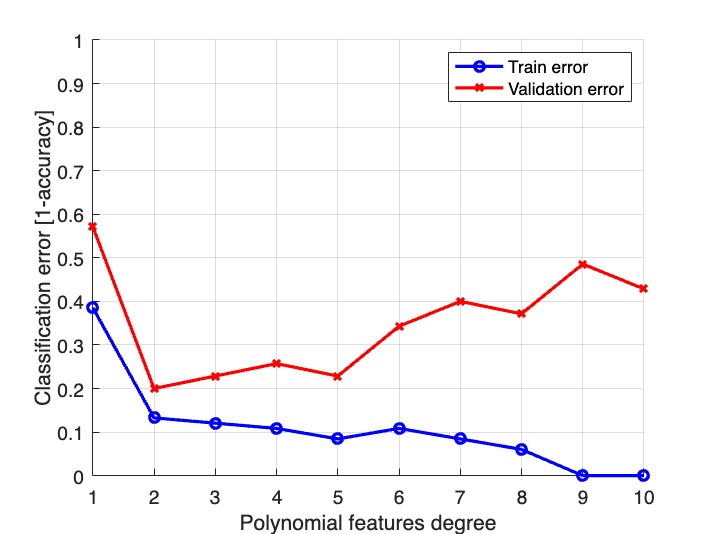


figure;
hold all
plot(1:degree_max, 1 - accuracy_train, 'bo-');
plot(1:degree_max, 1 - accuracy_validation, 'rx-');
grid on
xlim([1, degree_max]); ylim([0, 1]);
xlabel('Polynomial features degree');
ylabel('Classification error [1-accuracy]');
legend('Train error', 'Validation error')


sqrt(transpose(theta)*theta)

ans = 2.1269e+03